%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path


clearvars %clear all variables


# LaPlace

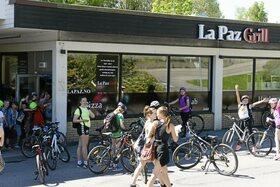

*Laplace Grill, Kolbotn*

**Fra f(t) til F(S)**

syms f(t) a b t s u
f(t) = t*sin(5*t)

$$f(t) = t\,\sin\left(5\,t\right)$$

F(s) = laplace(f);
Fsimpl = simplify(F);
if F == Fsimpl
    display(F)
else
    display(F), display(Fsimpl)
end

$$F(s) = \frac{10\,s}{{\left(s^{2}+25\right)}^{2}}$$

**First Shift**

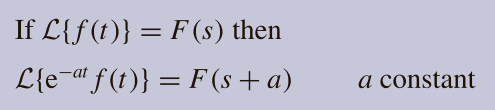

syms a t
a = 3;
firstShift = F(s+a);
firstShiftSimplified = simplify(firstShift);

if firstShift == firstShiftSimplified
    display(firstShift)
else
    display(firstShift),display(firstShiftSimplified)
end

$$firstShift = \frac{10\,\left(s+3\right)}{{\left({\left(s+3\right)}^{2}+25\right)}^{2}}$$

firstShiftExpForm = exp(-(a*t))*f(t)

$$firstShiftExpForm = t\,\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}$$

**Second Shift Theorem**

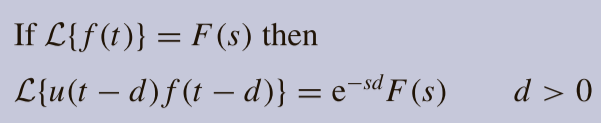

syms d
d = 1

d = 1

% secondShift=F()

 

**Invers Laplace**

syms f(t) a b t s S
F(S) = (s+3)/(s^3+5*s^2)

$$F(S) = \frac{s+3}{s^{3}+5\,s^{2}}$$


f(s) = ilaplace(F)

$$f(s) = \frac{3\,t}{5}-\frac{2\,{\mathrm{e}}^{-5\,t}}{25}+\frac{2}{25}$$

fSimpl = simplify(f)    

$$fSimpl(s) = \frac{3\,t}{5}-\frac{2\,{\mathrm{e}}^{-5\,t}}{25}+\frac{2}{25}$$